clc
clear all
close all

Solution 1:

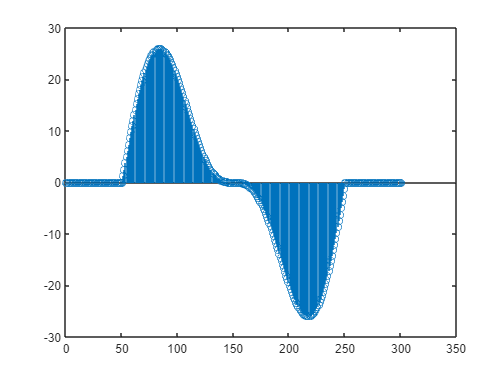

%1
n=0:200;
y=10*sin(n*pi/50)+20*sin(n*pi/100);
y1=[zeros(1,50) y zeros(1,50)];
yf=movmean(y1,50);
figure; 
stem(y1);

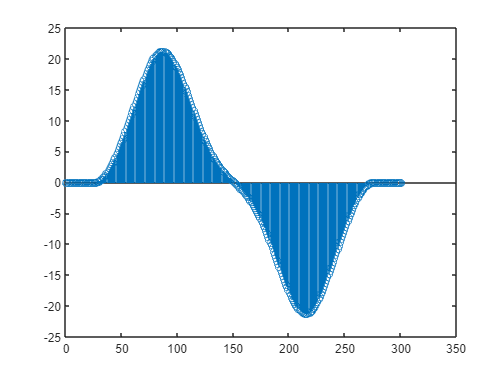

figure; 
stem(yf);

Solution 2:

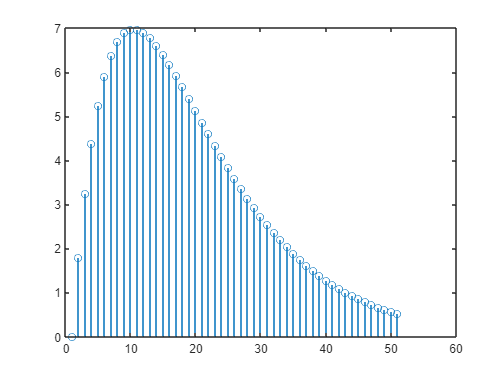

%2
n=0:50;
s=2*(n.*(0.9).^n);
figure
stem(s)

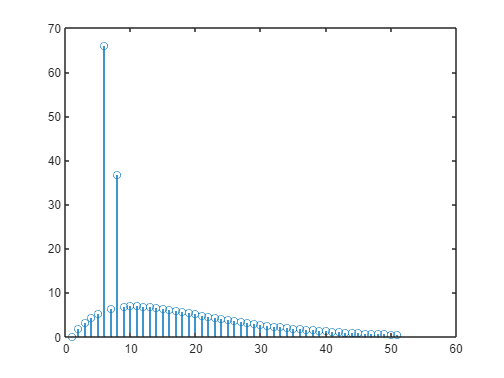

noise=60*[n-5==0]+30*[n-7==0];
noisy=s+noise;
figure
stem(noisy)

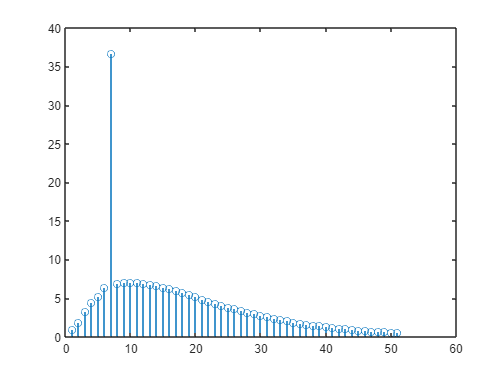

A1=movmedian(noisy,3);
figure
stem(A1)

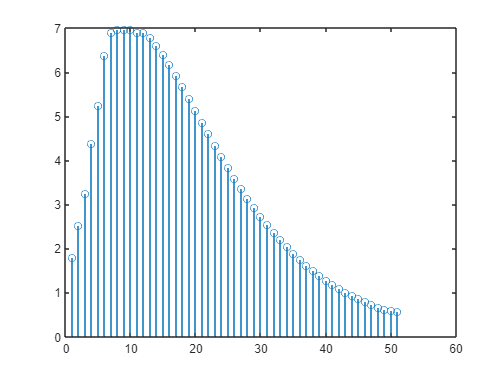

A2=movmedian(noisy,5);
figure
stem(A2)

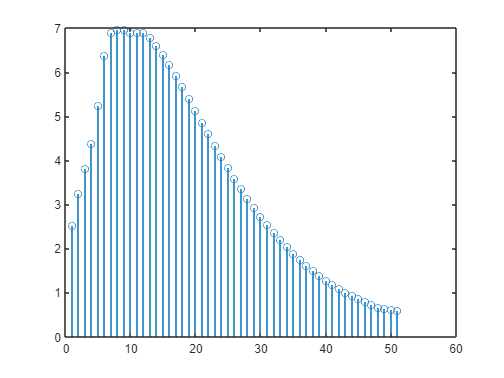

A3=movmedian(noisy,7);
figure
stem(A3)

Solution 3:

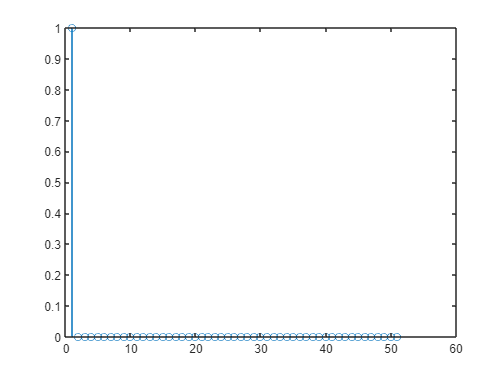

%3
n=0:50; % Indices 
b=[0.8,-0.44,0.36,0.02]; 
a=[1,0.7,-0.45,-0.6]; 
delta=[n==0]; 
Iresp=filter(b,a,delta);
units = [n>=0];
Sresp=filter(b,a,units); 
figure; 
stem(delta); 

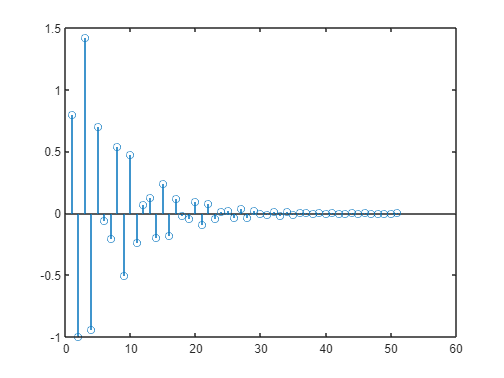

figure;
stem(Iresp);

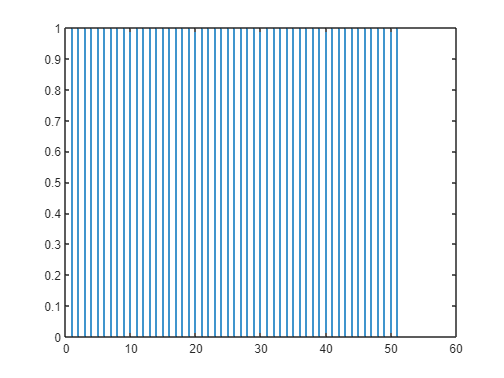

figure; 
stem(units);

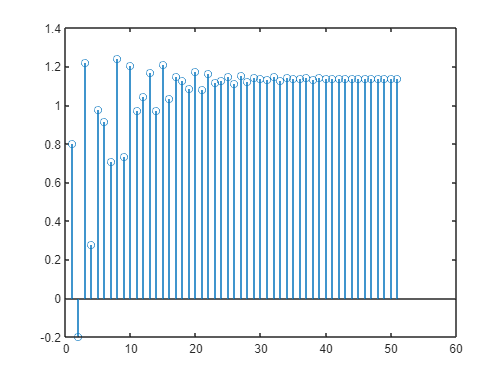

figure; 
stem(Sresp);

Solution 4:

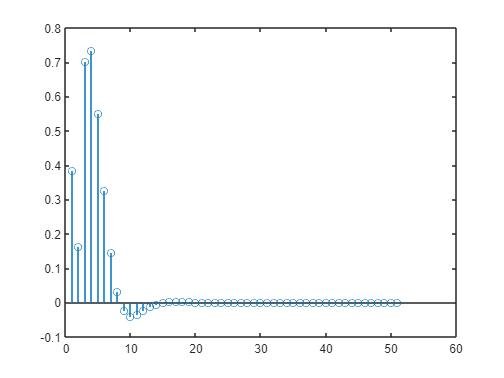

%4
b=[0.0675, 0.1349, 0.675];  
a=[1,-1.143, 0.4128]; 
y=[1,2]; 
inicias = filtic(b,a,y); 
delta=[n==0]; 
Iresp = filter(b,a,delta,inicias) ;
units = [n>=0];
Sresp = filter(b,a,double(units),inicias);
figure;
stem(Iresp);

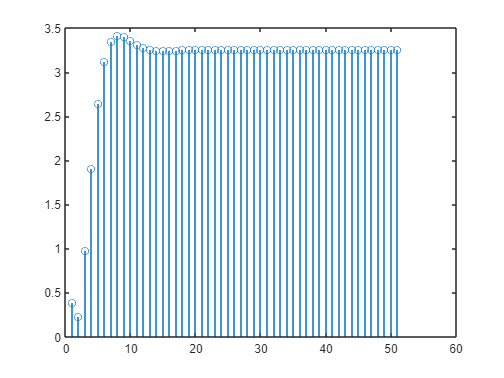

figure;
stem(Sresp);

Solution 5:

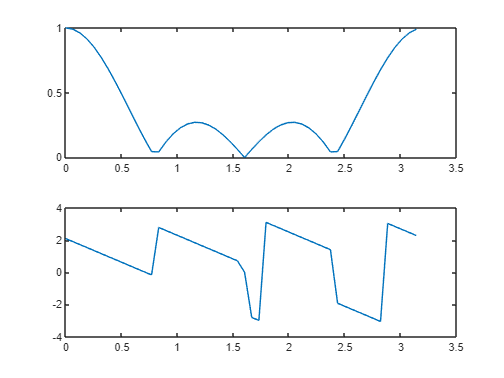

%5
n=0:49;
omega=0:pi/49:pi;
h=[ones(1,4)/4  zeros(1,46)];
noisy=exp(j*50*pi/3);
y=conv(noisy,h);
Yw=fft(y);

subplot(2,1,1);
plot(omega,abs(Yw));
subplot(2,1,2);
plot(omega,angle(Yw));

Solution 6:

%6

Solution 7:

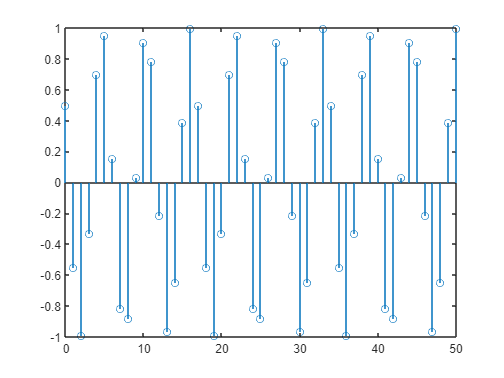

%7
n=0:50; 
noisy=cos(6*pi*n/17+pi/3); 
FT=fft(noisy);
xn1=ifft(FT); 
figure; 
stem(n,noisy); 

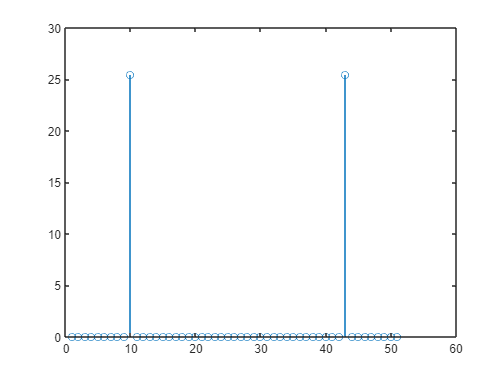

figure; 
stem(abs(FT));

figure; 
stem(n,xn1); 

Solution 8:

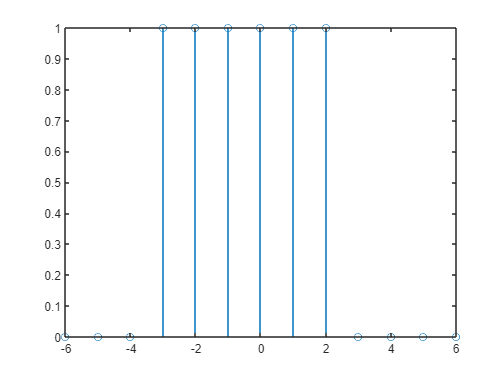

%8
n=-6:6; % Indices
x5= [(n+3) >= 0]-[(n-3) >= 0]; % Sequence
D=fft(x5);
figure; 
stem(n,x5);

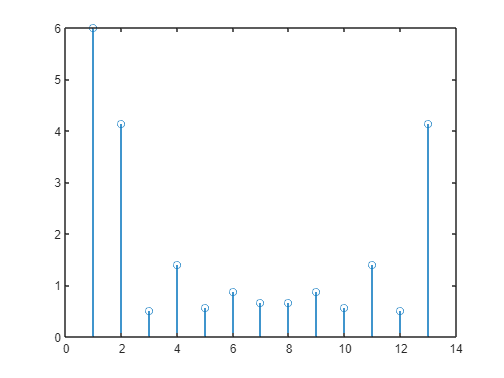

figure; 
stem(abs(D));

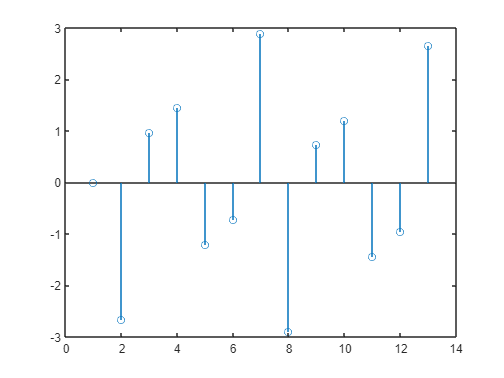

figure; 
stem(angle(D));